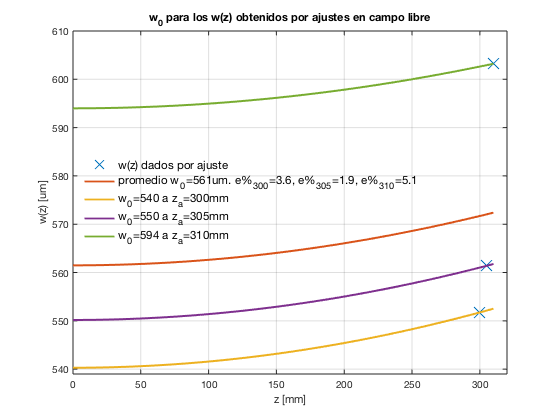

clear all;
close all;

%Obtencion de w0 a partir de los w_prom a cada distancia para campo libre

lambda0 = 632.8E-9; 
pixel = 25E-6; %tamano de cada pixel

% nomenclatura: w_prom_z = [w_prom_300 w_prom_305 w_prom_310]
w_prom_z = [22.070 22.456 24.129]; %estos son pixeles
w_prom_z = w_prom_z * pixel; %w(z) en mm
z_a = [300E-3 305E-3 310E-3]; %posiciones de captura de imagen
z= 0:0.001:0.310;

%Obtengo A=w0^2 utilizando la resolvente con la suma de sqrt(discriminante)
%va a haber un w0 que no va a ser logico
%w_0 es real, y no muy distinto a los valores del ajuste
%ya que el haz se ensancha poco en el camino libre

% a x^2 + b x + c = 0
for i=1:3
    a=1;
    b=-w_prom_z(i)^2;
    c=( (z_a(i)*lambda0)/ pi)^2;
    A_raiz_mas(i) = (-b + sqrt(b^2-4*a*c) )/(2*a);
    A_raiz_menos(i) = (-b - sqrt(b^2-4*a*c) )/(2*a);
    w0_mas(i) = sqrt(A_raiz_mas(i));
    w0_menos(i) = sqrt(A_raiz_menos(i));
    %A_raiz_mas(i) = (w_prom_z(i)^2 + sqrt( w_prom_z(i)^4 - 4*((z_a(i)*lambda0) /pi)^2 ))/2;
    %A_raiz_menos(i) = (w_prom_z(i) - sqrt( w_prom_z(i) - 4*((z_a(i)*lambda0) /pi)^2 ))/2;
end

%A_raiz_mas
%A_raiz_menos
w0_mas;
%w0_menos
w0_prom = mean(w0_mas);

%Error del w(z) con w0_prom. error_wz_w0prom = [error_300 error_305 error_310]
for i=1:3
    w_z_w0prom(i)=sqrt((w0_prom^2 *( 1+ ( (z(296+i*5)*lambda0)/(pi*w0_prom^2) ).^2 )));
    error_wz_w0prom(i) = (w_z_w0prom(i)/w_prom_z(i));
end
error_wz_w0prom = abs(100*(1-error_wz_w0prom));

%Grafico para verificar w(x) con w0 obtenido
figure()
plot(1E3*z_a,1E6*w_prom_z,'x','Markersize',14,'LineWidth',1.2);
hold on;
grid on;
plot(1E3*z,1E6*sqrt((w0_prom^2 *( 1+ ( (z*lambda0)/(pi*w0_prom^2) ).^2 ))  ),'LineWidth',1.7);
for i=1:3    
    plot(1E3*z,1E6*sqrt((w0_mas(i)^2 *( 1+ ( (z*lambda0)/(pi*w0_mas(i)^2) ).^2 ))  ),'LineWidth',1.7);
end
title('w_0 para los w(z) obtenidos por ajustes en campo libre');
ylabel('w(z) [um]')
xlabel('z [mm]')
axis([0 320 539 610]);
legend('w(z) dados por ajuste', ...
    sprintf('promedio w_0=%.fum. e%%_{300}=%.1f, e%%_{305}=%.1f, e%%_{310}=%.1f',w0_prom*1E6,error_wz_w0prom(1),error_wz_w0prom(2),error_wz_w0prom(3)), ...
    sprintf('w_0=%.f a z_a=300mm',w0_mas(1)*1E6), ...
    sprintf('w_0=%.f a z_a=305mm',w0_mas(2)*1E6), ...
    sprintf('w_0=%.f a z_a=310mm',w0_mas(3)*1E6), ...
    'location','west','Fontsize',11.5,'box','off');
%print(sprintf('fig_w(z)_libre'),'-dpng');